# Missed Topics

### LOGICAL ARRAY

A = 1 : 10;
A > 3

A(A > 3)

A = randi(10, [3, 3]);
A(A > 3)

### SOME USEFUL MATRIX OPERATIONS

A = magic(3);

fliplr(A)

flipud(A)

[m, p] = min(A(:))

### SIGNAL ANALIZER

t = linspace(0, 2 * pi);
x = sin(t);
% ADDING NOISE
x(20) = x(20) + 0.7;
x(70) = x(70) - 0.7;
plot(t, x, 'LineWidth', 2);
title("Noisy Signal");

ECG SIGNAL

load ecg.mat
signal = ecg + 0.1 * randn(size(ecg));
plot(signal)

# Image

`Color Image is just a 3D Matrix containing the RED, GREEN and BLUE components in 3 different 2D Matrices.`

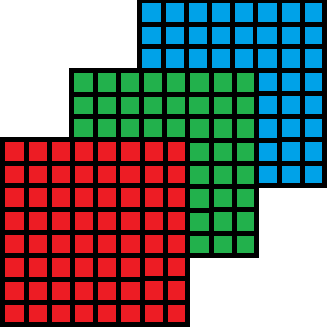

IMAGE STRUCTURE

### LOADING IMAGE

`You can load an image file into a matrix using the ``imread()`` function. This function supports ``.jpg, .png, .bmp`` and other image formats.`

I = imread('colors.png');

### DISPLAYING IMAGE

`Use the`` imshow() ``function to display an image matrix.`

imshow(I)
title("An Image File")

### R G B

`Color images have separate Red, Green and Blue channels`

R = I(:, :, 1);
G = I(:, :, 2);
B = I(:, :, 3);

imshow(R);
imshow(G);
imshow(B);

### IMAGE IS JUST A MATRIX

`You can use the typical matrix operations on a image just like a regualr matrix.`

I(100:200, 100:200, :) = 0;
imshow(I)

### CROPPING

`You can use ``imcrop()`` function to crop an image.`

I = imread('shop_front.jpg');
imshow(I);

cropped = imcrop(I, [170, 100, 300, 90]);
imshow(cropped);

### RESIZING

`Use ``imresize()`` to resize an image.`

resized = imresize(cropped, [30, 100]);
imshow(resized);

### GRAYSCALE

`Grayscale images have only a single channel compared to 3 channels of an RGB image. So these images are easier to process. You can use the ``rgb2gray()`` function to do that.`

gray = rgb2gray(cropped);
imshow(gray)

### ENHANCING

`You can use the ``imadjust()`` function to adjust the contrast of the image.`

adjusted = imadjust(gray, [0.5, 1], [0, 1]);
imshow(adjusted);

# Edge Detection

### CONVOLUTION

A = [zeros(5, 10); ones(5, 10)]
B = [1, 0; 0, -1]

conv2(A, B)

### EDGE DETECTION

I = imread("colors.png");
I = rgb2gray(I);
imshow(I);
e = conv2(I, B) .* conv2(B, I);
imshow(e)

e2 = edge(I, 'Canny');


imshow(e2);

# Segmentation

### COLOR SEGMENTATION

i = imread('color_segmentation.jpg');
imshow(i);

r = i(:, :, 1);
imshow(r);

g = i(:, :, 2);
g = ~ imbinarize(g, 0.1);
imshow(g);

b = i(:, :, 3);
imshow(b);

[L, N] = bwlabel(g);
stats = regionprops(g,'Centroid',...
    'MajorAxisLength','MinorAxisLength')

center = stats.Centroid
diameter = (stats.MajorAxisLength + ...
    stats.MinorAxisLength) / 2;

imshow(i)
hold on;
viscircles(center, diameter / 2, ...
    'EdgeColor', 'k', 'LineWidth', 3);
hold off;

### CLEANING

i = imread('coins.png');
bin = imbinarize(i, 0.3);
imshow(bin);

filled = imfill(bin, 'holes');
imshow(filled);

SE = strel('disk', 10);
seg = imopen(filled, SE);
imshow(seg)

[L, N] = bwlabel(seg);
title(strcat("Num Objects : ", string(N)))

# Object Recognition

### WEBCAM

clear cam;
cam = webcam;
while true
    i = cam.snapshot;
    flipped = fliplr(i);
    image(flipped);
    drawnow;
end

### DEEP LEARNING

clear cam;
cam = webcam;
nnet = alexnet;
while true
    i = cam.snapshot;
    flipped = fliplr(i);
    resized = imresize(flipped, [227, 227]);
    label = classify(nnet, resized);
    image(flipped);
    title(char(label));
    drawnow;
end

### WHAT ELSE?

### [TRANSFER LEARNING](https://www.youtube.com/watch?v=NQjoaptSEoo)